# Universidade Federal de Campina Grande

# Programa de Pós-Graduação em Engenharia Elétrica

# Estimação e Identificação de Sistemas - 21.2

## Professores: Antonio Marcus Nogueira Lima, Dr.

##                        **Saulo** Oliveira **Dornellas** Luiz, Dr.

## Aluno: Arthur Dimitri Brito Oliveira

O objetivo deste relatório é a descrição dos aspectos a serem levados em consideração ao realizar a identificação de um sistema desconhecido. A aquisição de dados e a análise da qualidade destes, ao empregar o método de mínimos quadrados, são aqui abordadas. 

## Relatório de Atividade 9

### Introdução

O processo de identificação almeja a obtenção de um modelo confiável. Para isso, decisões de projeto devem ser adotadas, como a escolha do algoritmo de estimação a ser empregado, o tipo de modelo, o projeto do experimento. Tais opções podem ser denominadas como sendo:

$\mathcal{D} = $ {variáveis de projeto}

Um bom modelo é aquele que atende os critérios de qualidade para um determinado uso. Para avaliar tal qualidade, deve-se assumir algumas coisas sobre o processo. Considerando que o seguinte modelo descreve os dados da planta:


$$y(t) = G_0(q)u(t)+H_0(q)e_0(t)$$


sendo $e_0(t)$um ruído branco de variância $\lambda_0$. Em uma notação mais compacta, tem-se:

        $T_0(q) = [G_0(q) \:\: H_0(q)]$    (1)

Supondo que as variáveis de projeto $\mathcal{D}$ foram escolhidas, o modelo estimado é dado por:


$$\hat{T}(q,\mathcal{D})=[\hat{G}(q,\mathcal{D})\;\;\hat{H}(q,\mathcal{D})]$$


Deseja-se que o erro entre o modelo estimado e o modelo real seja mínimo. Assim:


$$\tilde{T}(e^{j\omega},\mathcal{D}) \stackrel{\Delta}{=} \hat{T}(e^{j\omega},\mathcal{D})-T_0(e^{j\omega})$$


De modo a definir uma métrica formal para o caso onde há uma maior importância em algumas faixas de frequência, introduz-se o critério de frequência escalar ponderado: 

        $J_1(\tilde{T}(\cdot,\mathcal{D}))=\int_{-\pi}^{\pi}\tilde{T}(e^{j\omega},\mathcal{D})C(\omega)\tilde{T}^T(e^{-j\omega},\mathcal{D})d\omega$        (2)


$$C(\omega)=\left[\matrix{ C_{11}(\omega) &  C_{12}(\omega) \cr C_{21}(\omega) &C_{22}(\omega)}\right]$$


A matriz $C(\omega)$descreve a importância relativa de um bom ajuste em diferentes frequências, bem como a importância relativa das funções de transferência $G$ e $H$. 

$J_1$ é uma variável aleatória devido à aleatoriedade de $\hat T$. De modo a obter uma realização independente da qualidade de medição, pode-se tomar a esperança de $J_1$:

        $\bar{J}(\mathcal{D})=\int_{-\pi}^{\pi}E[\tilde{T}(e^{j\omega},\mathcal{D})C(\omega)E\tilde{T}^T(e^{-j\omega},\mathcal{D})]d\omega = \int_{-\pi}^{\pi}\text{tr}[\Pi (\omega,\mathcal{D})C(\omega)]d\omega$        (3)

        $\Pi(\omega,\mathcal{D})=\tilde{T}^T(e^{-j\omega},\mathcal{D})\tilde{T}(e^{j\omega},\mathcal{D})$        (4)

Uma formulação compacta para o problema de escolha das variáveis de projeto pode ser expressa por:


$$\min_{\mathcal{D}\in\Delta}\bar{J}(\mathcal{D})$$


### Exemplo I: Simulação

Considerando um sistema do tipo:


$$y_\mathcal{D}(t)= \hat{G}(q,\mathcal{D})u^*(t)$$


A saída real do sistema é dada por:


$$y_0(t)=G_0(q)u(t)$$


O sinal de erro é, então:


$$\tilde{y}_\mathcal{D}=y_\mathcal{D} -y_0(t)=[\hat{G}(q,\mathcal{D})-G_0(q)]u(t)$$


Analisando no espectro, o erro é dado por: 


$$\Phi_{\tilde{y}}(\omega,\mathcal{D})=|\hat{G}(q,\mathcal{D})-G_0(q)|^2\Phi_{u}^*(\omega)$$


Agora introduz-se a métrica de **degradação média de desempenho **devido a erros no modelo $\hat G$:


$$\Psi_{\tilde{y}}(\omega,\mathcal{D})=E[|\hat{G}(q,\mathcal{D})-G_0(q)|^2\Phi_{u}(\omega)]$$


Sabendo que $\Pi(\omega,\mathcal{D})=\tilde{T}^T(e^{-j\omega},\mathcal{D})\tilde{T}(e^{j\omega},\mathcal{D})$ e $C(\omega)=\left[\matrix{\Phi_{u}(\omega) &  0\cr 0&0}\right]$, pode-se reescrever a equação da degradação média como sendo:


$$\Psi_{\tilde{y}}(\omega,\mathcal{D}) = \text{tr}[\Pi (\omega,\mathcal{D})C(\omega)]$$


Por fim, a variância média $\bar E[\tilde{y}^2(t)]$ é expressa por:


$$2\pi E[\tilde{y}^2(t)]=\bar{J}(\mathcal{D})=\int_{-\pi}^{\pi}\Psi_{\tilde{y}}(\omega,\mathcal{D})d\omega$$


Esse é um caso especial de $J_1$ e ilustra como o critério de projeto quadrático pode ter uma interpretação física. 

### Exemplo II: Predição

A predição um passo à frente é dada por:


$$\hat{y}(t|t-1)= H^{-1}(q)G(q)u(q)-[1-H^{-1}(q)]y(t)$$


O erro de predição em relação aos dados reais é dado por:


$$\tilde{y}_\mathcal{D}(t|t-1) = [\hat H^{-1}(q)\hat G(q) - H^{-1}_0(q)G_0(q)]u(t)-[H^{-1}_0(q)-\hat {H}^{-1}(q)]y(t)$$


Os dados de entrada e saída são do tipo:


$$y^*(t) = G_0(q)u^*(t) + H_0(q)e_0(t)$$


Assim, o erro de predição se torna:


$$\tilde{y}_\mathcal{D}(t|t-1) =\hat H^{-1}[\tilde{G}(q)u(t)+\tilde{H}e_o]  = \hat H^{-1}(q,\mathcal{D})\tilde{T}(q,\mathcal{D})
\left[\matrix{u(t)\cr e_0(t)}\right]$$


O espectro desse sinal é:


$$\Phi_{\tilde{y}}(\omega,\mathcal{D})=\frac{1}{|\hat{H}(e^{j\omega})|^2}\tilde{T}(e^{j\omega},\mathcal{D})
\left[\matrix{
\Phi_u(\omega)&\Phi_{ue}(\omega)\cr
\Phi_{ue}(\omega)&\lambda_0}\right]

\tilde{T}^T(e^{-j\omega},\mathcal{D})
$$


Devido à presença de $\hat H$ no denominador da expressão anterior, essa equação não é quadrática no modelo de erro. No entanto, assumindo que o erro seja pequeno a ponto que os termos de maior ordem de $\tilde T$ sejam desprezados, podemos substituir $\hat H$ por $H_0$. Assim, tem-se o espectro médio do sinal de erro:


$$\Psi_{\tilde{y}}(\omega,\mathcal{D}) = \text{tr}[\Pi (\omega,\mathcal{D})C(\omega)]$$



$$C(\omega)=\frac{1}{|H_0(e^{j\omega})|^2}\left[\matrix{
\Phi_u(\omega)&\Phi_{ue}(\omega)\cr
\Phi_{ue}(\omega)&\lambda_0}\right]$$


### Viés e Variância

Utilizando a mesma formulação, apresentada na Eq.1, para o sistema e utilizando $\hat \theta_N(\mathcal{D})$ como a estimativa dos parâmetros, a função de transferência estimada pode ser representada por: 


$$\hat T_N(e^{j\omega}.\mathcal{D})=T(e^{j\omega},\hat \theta_N(\mathcal{D}))$$


O valor médio da estimava convergente para o valor real pode ser expresso por: 


$$T(e^{j\omega},\hat{\theta}_N(\mathcal{D}))\approx T(e^{j\omega},{\theta}^\ast(\mathcal{D}))+\big[\hat{\theta}_N(\mathcal{D})-{\theta}^\ast(\mathcal{D})\big]^T\,T^{'}(e^{j\omega},{\theta}^\ast(\mathcal{D}))$$


Introduzindo a notação para a diferença do modelo no limite $N=\infty$:


$$B(e^{j\omega},\mathcal{D})=T(e^{j\omega},\theta^*(\mathcal{D}))-T_0(e^{j\omega})$$


O MSE $\Pi_N(\omega,\mathcal{D})$ é expresso por:


$$\Pi_N(\omega,\mathcal{D})\approx B^T(e^{-j\omega},\mathcal{D})B(e^{j\omega},\mathcal{D})+\frac{1}{N}P(\omega,\mathcal{D})$$


Sendo $P(\omega,\mathcal{D})$ expresso por:


$$P(\omega,\mathcal{D}) = {T^{'}}^T(e^{-j\omega},\theta^\ast(\mathcal{D}))[N\cdot\text{Cov}\hat{\theta}_N(\mathcal{D})]T^{'}(e^{j\omega},\theta^\ast(\mathcal{D}))$$


O projeto do critério do modelo, na forma das Eq.3 e Eq.4, pode ser dado como sendo:


$$\bar{J}(\mathcal{D})=J_P(\mathcal{D})+J_B(\mathcal{D})$$



$$J_P(\mathcal{D})= \frac{1}{N}\int_{-\pi}^\pi\text{tr}[P(\omega,\mathcal{D})C(\omega]d\omega$$



$$J_B(\mathcal{D})=\int_{-\pi}^{\pi} B^T(e^{-j\omega},\mathcal{D})B(e^{j\omega},\mathcal{D})d\omega$$


A expressão em termos de $J(\mathcal{D})$ enfatiza a característica básica da contribuição de $J_p$ e uma contribuição quanto ao viés $J_b$ para o critério objetivo. Ambas são afetadas pelas variáveis de projeto em diferentes maneiras. O termo de viés é tipicamente afetado pelo conjunto de modelos (quanto mais generalista, menor o viés). Já o termo de variância decresce com grandes quantidades de dados, e tende a crescer com a quantidade de parâmetros estimados. 

### Projeto do Experimento

Projetar um experimento é uma tarefa que deve resultar em dados suficientemente informativos a respeito do sistema. Nesse contexto, a escolha dos sinais de entrada tem uma influência substancial nos dados observados, e existem diferentes aspectos associados à escolha deles. 

Um deles está relacionado às propriedades de segunda ordem do sinal de entrada $u$, como o seu espectro $\Phi_u(\omega)$ e o espectro cruzado com o erro de realimentação $\Phi_{ue}(\omega)$. Outro aspecto está associado à forma dos sinais de entrada, podendo ser senoides somadas, sinais PRBS, entre outros. 

#### Princípios norteadores

Aqui denota-se $X$ como sendo todas as variáveis associadas ao experimento. As propriedades assintóticas da estimativa por $\theta^*(X)$. A covariância assintótica da matriz de parâmetros a serem estimados é dada por:


$$P_{\theta}(X) \sim \lambda_0 \left [E\left(\frac{d}{d\theta} \hat {y}(t|\theta)\right)\left(\frac{d}{d\theta}\hat y(t|\theta)\right)^T\right]^{-1} $$


Vale-se salientar que, se há a suspeita de que o sistema é não-linear, dado que o modelo a ser utilizado é a melhor aproximação do sistema, diante de um conjunto de variáveis $X$, o experimento deve ser realizado ao redor de um ponto de operação da planta. Ademais, uma vez que $X$ é escolhido de tal forma que a matriz de covariância $P_\theta(X)$ seja minimizada. Uma pequena variância em uma determinada componente de $\theta$ é resultado de uma sensibilidade elevada da matriz a tal componente. 

Assim, esse tipo de princípio deve dar uma ideia geral de como projetar o experimento. Isto é aplicável ao problema dos sensores, à seleção das variáveis de entrada e a outros aspectos de projeto. 

#### Experimentos em malha aberta

Supondo que os parâmetros $\theta_1 \:\:e\:\: \theta_2$ correspondam a diferentes modelos em $\mathcal{M^*$. Dado que $\varepsilon_i(t)=\varepsilon(t,\theta_i)$, $G_i(q)=G(q,\theta_i)$, $\Delta G(q)=G_2(q)-G_1(q)$. Assim:


$$\Delta\varepsilon(t) = \varepsilon_1(t)-\varepsilon_2(t) = \frac{1}{H_1(q)}[\Delta G(q)u(t)+\Delta H(q)\varepsilon_2(t)]$$


$G_0 \:\: e \:\: H_0$ são a descrição do sistema real. Caso o experimento seja realizado em malha aberta, é evidente que $u(t)$ e $e(t)$ são independentes. Utilizando o teorema definido no capítulo 2:


$$\bar{E}[\Delta\varepsilon(t)]^2=\frac{1}{2\pi}\int_{-\pi}^\pi\frac{1}{|H_1(e^{j\omega})|^2}\Bigg(\left|\Delta G(e^{j\omega})+\frac{G_0(e^{j\omega})-G_2(e^{j\omega})}{H_2(e^{j\omega})}\Delta H(e^{j\omega})\right|^2\Phi_u(\omega)+|\Delta H(e^{j\omega})|^2\left|\frac{H_0(e^{j\omega})}{H_2(e^{j\omega})}\right|^2\lambda_0\Bigg]d\omega$$


Diante da suposição que os dados sejam não-informativos com relação a $M^*$, de tal forma que:


$$\bar E[\Delta \varepsilon(t)]^2=0$$


A equação anterior implica que os termos dentro dos colchetes devem ser nulos, de tal modo que:


$$\Delta H(e^{j\omega})=0$$



$$|\Delta G(e^{j\omega})|^2\Phi_u(\omega)\equiv0$$


Caso o espectro do sinal de entrada em malha aberta $\Phi_u(\omega)$ implique em $\Delta G(e^{j\omega})=0$, isso implica que os modelos são iguais e que os dados representam bem o sistema. 

Um sinal $u(t)$, com espectro $\Phi_u$, é dito persistentemente excitante e de ordem n para filtros da forma: 


$$M_n(q)= m_1q^{-1} + ... + m_nq^{-n}$$


A relação:


$$|M_n(e^{j\omega})|^2\Phi_u(\omega)\equiv0$$


Implica que:


$$M_n(e^{j\omega})\equiv0$$


Ainda de acordo com o teorema 2.2 definido no capítulo 2, $|M_n(e^{j\omega})|^2\Phi_u(\omega)$ é o espectro do sinal $v(t)=M_n(q)u(t)$. Sendo assim, um sinal que é persistente de ordem $n$ não é zerado quando um filtro de média móvel de $(n-1)$-ésima ordem é aplicado a ele. Pode-se definir o lema 13.1:

*Dado um sinal quasi-estacionário, a matriz *$\bar R_n$ *de dimensões *$nxn$ *definida por:*


$$\bar R_n=\left[\matrix{
R_u(0)&R_u(1)&...&R_u(n-1)\cr
R_u(1)&R_0(u)&...&R_u(n-2)\cr
\vdots&\vdots&\ddots&\vdots\cr
R_u(n-1)&R_u(n-2)&...&R_u(0)
}\right]$$


$u(t)$ *é dito persistente de ordem n se, e somente se, a matriz *$\bar R_n$ *for não-singular. *

### Exemplo 13.1: sinais gaussianos e binários - bandas limitadas

Deseja-se uma entrada com potência concentrada na banda $1 \leq \omega \leq2$ rad/s e $e(t)$sendo gerado como um ruído gaussiano. Tal sinal é filtrado por um filtro Butteworth de quinta ordem. A reprodução dos resultados pode ser visualizado na Figura 1 e na Figura 2. 

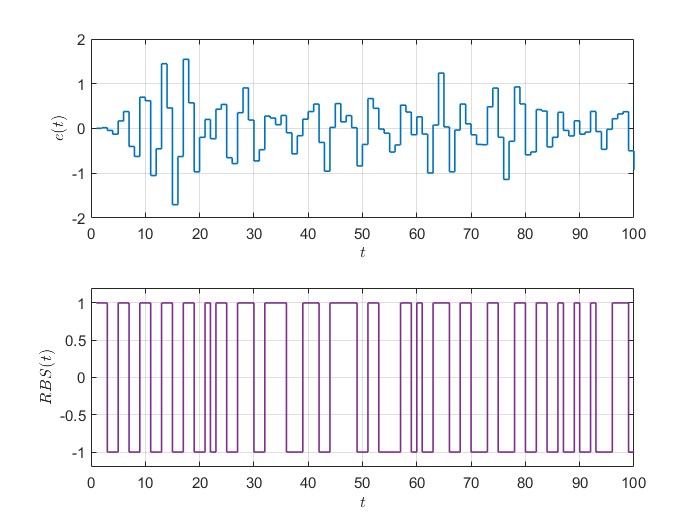

Ex13_1_1

**Figura 1: **curva superior: ruído gaussiano filtrado por um filtro passa-banda. Curva inferior: sinal binário aleatório obtido a partir do ruído gaussiano. 

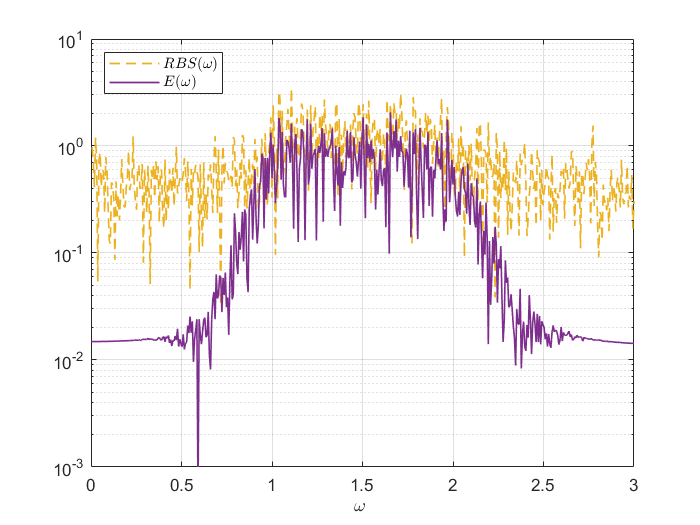

Ex13_1_2

**Figura 2: **espectro dos sinais ilustrados na Figura 1. A curva sólida representa o espectro do ruído gaussiano, enquanto que a pontilhada representa o espectro do sinal binário. 

Um sinal PRBS pode ser, também, utilizado, dada a sua característica determinística, tendo propriedades semelhantes ao ruído branco. Esse tipo de sinal pode ser gerado pela equação de diferença a seguir:


$$u(t)={rem}(A(q)u(t))=rem(a_1u(t-1)+...+a_n(u(t-n),2)$$


 O vetor de entradas $[u(t-1) \:\: ... \:\: u(t-n)]$ pode assumir, somente, $2^n$ valores diferentes. Uma outra escolha natural é formar o vetor de entrada como uma soma de senoides. Assim:


$$u(t) = \sum_{k=1}^{d}a_k\cos (\omega_k t+\phi)$$


Exceto quanto aos efeitos do transiente, o espectro do sinal de entrada pode ser expresso por:


$$\Phi_u(\omega)=2\pi\sum_{k=1}^{d}\frac{a_k^2}{4}[\delta(\omega-\omega_k)+delta(\omega+\omega_k)]$$


Ajustando $d, \:\:a_k \:\: e\:\: \omega_k$ pode-se projetar o sinal de forma muito precisa para as frequências desejadas. No entanto, um dos problemas com a entrada é o fator de *crest, *isto é, a potência do sinal $\sum a_k^2/2$. Caso todas as senoides estejam em fase, a amplitude quadrada será $(\sum a_k^2/2)^2$ e o fator de *crest* pode assumir valores até $\sqrt{2d}$. Uma das formas de corrigir isso é escolher fases $\phi(k)$de tal forma que os cossenos estejam tão defasados quanto possível. Nessa linha, utilizar a escolha da fase por meio de Schroeder, de tal forma que as fases estejam espalhadas $\phi_k=\phi_1-\frac{k(k-1)}{d}\pi, \:\: 2 \leq k \leq d$, com $\phi$ arbitrário. 

### Exemplo 13.2:

Aqui o sinal de entrada é obtido a partir de 10 frequências de mesma amplitude, igualmente espalhadas dentro do espectro de $1 \leq \omega \leq 2 $ rad/s. Varia-se o valor de $\phi_k$ a partir de um valor nulo, passando pela determinação das fases por meio do método de Schroeder, e, por fim, utilizando fases aleatórias. A evolução temporal dos sinais pode ser visualizada na Figura 3, enquanto que o espectro pode ser visualizado na Figura 4. 

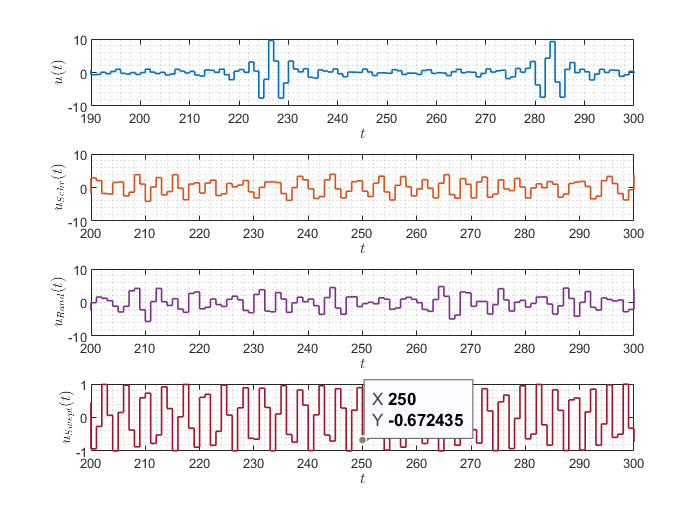

Ex13_2_1

**Figura 3: **visualização dos sinais como soma de senoides. O gráfico em azul representa a soma de senoides não defasadas. A curva em laranja ilustra as defasagens geradas por meio de Schroeder. A curva em roxo representa a curva gerada por defasagens aleatórias. A última ilustra o cosseno *swept. *

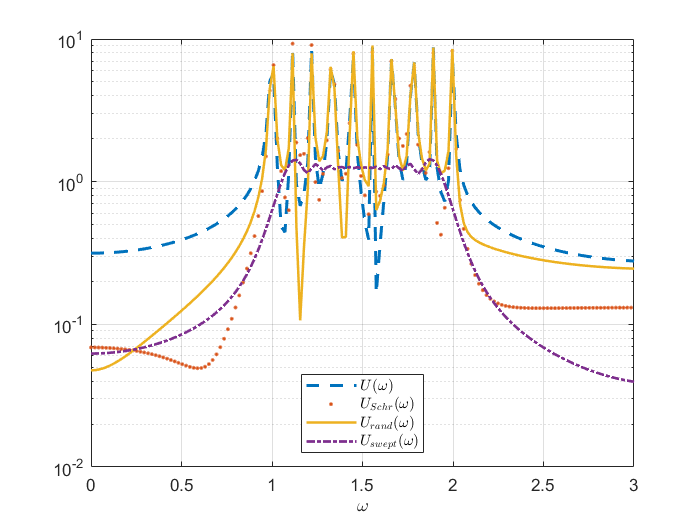

Ex13_2_2

**Figura 4: **ilustração do espectro das diferentes variações de $U(\omega)$.

Fica evidente que o método denominado de *swept cosine *resulta em uma suavização nos domínios do tempo e frequência. 

### Pré-processando os dados

Em grande parte dos casos, os dados coletados no experimento de identificação não podem ser utilizados de forma imediata em algoritmos de identificação. Isso se dá, por exemplo, devido a perturbações de alta frequência presentes nos dados, *outliers, *ou perturbações de natureza periódica. Tais variações não são incomuns e normalmente são provenientes de fontes externas.

O que pode-se fazer é remover as perturbações mediante um tratamento explícito dos dados, ou assumir que o modelo conseguirá lidar com as perturbações. 

### Exemplo 14.1: Outliers

Considerando um sistema descrito pela seguinte equação de diferença:


$$y(t) = -2.85y(t-1)+2.717y(t-2)-0.865y(t-3)\\=
u(t-1)+u(t-2)+u(t-3)+e(t)+0.7e(t-1)+0.2e(t-3)$$


O enunciado menciona que as amostras do sinal são anuladas, posteriormente, de $y(313)$ a $y(320)$. A evolução temporal do sinal de saída e o resíduo associado à estimativa pode ser visualizados na Figura 5. Pode-se observar que o resíduo tem um incremento muito elevado na faixa de valores discrepantes (nulos) da saída do sistema. 

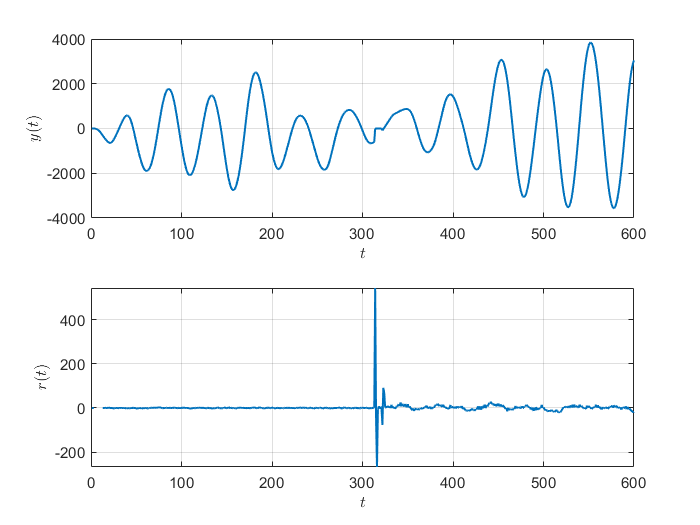

model1

De modo a corrigir isso, um segundo modelo de mínimos quadrados foi utilizado. Dessa vez, ao invés de utilizar todas as amostras do sinal, há um truncamento antes do trecho onde $y(t)$ começa a ser nulo. O comparativo quanto a aproximação de coeficientes pode ser visualizado a seguir. 

model2

theta_model1 =    -1.5412    0.1223    0.4409    2.0896    0.1830    4.4264


theta_model2 =    -2.9023    2.8212   -0.9178    1.0224    0.9420    0.8867


Devido à presença dos outliers, o modelo 1 diverge dos valores esperados para os coeficientes, enquanto que o modelo 2 se aproxima significativamente destes valores. 

## Referências

[1]   L. LJUNG.** System Identification: Theory for the User **Courier Corporation, 2008. ISBN 0486462781.